Make a monochrome version of the glc ring figure for a grant application

v.diff_glc = 1e-6;
model = buildScerevisiaeModel(v,model_default,'sCerevisiae_ring','proportional');

layout = buildCelOptLayout(model);

layout.xdim = 51;
layout.ydim = 51;
layout = setInitialPop(layout,'colonies',1e-4,false);
stridx('glc__D_e',layout.mets);
layout.initial_media(70,1,1,1:2) = 0;
layout.initial_media(70,26,26,1) = 1;
layout.initial_media(70,26,26,2) = 1e-5;
layout.params.mediaLogName = 'C:\sync\biomes\cellulose\optima\temp\log_media_ringForGrant.m';
layout.params.writeBiomassLog = 0;
layout.params.mediaLogRate = 25;
layout.params.maxCycles = 600;
layout.params.spaceWidth = 0.01;
layout.params.timeStep = 1/60;

runComets(layout);

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


media = parseMediaLog('C:\sync\biomes\cellulose\optima\temp\log_media_ringForGrant.m',{'glc__D_e'});

ts = 400;
mat = zeros(layout.xdim,layout.ydim);

rdat = media(media.t == ts,:);
[rows, cols] = size(rdat);
for i = 1:rows
    row = rdat(i,:);
    mat(row.x,row.y) = row.amt;
end
mat = mat/max(max(mat));

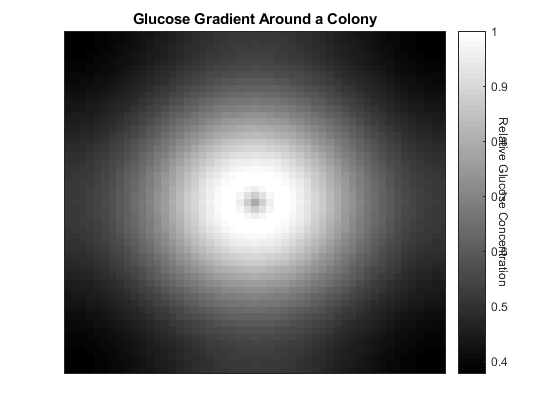

colormap('gray')

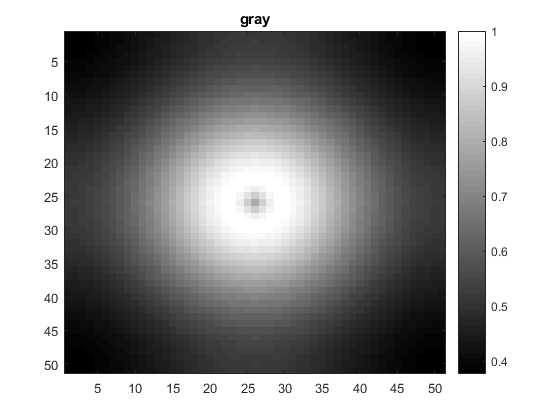

image(mat,'CDataMapping','scaled')
c = colorbar
title('gray')

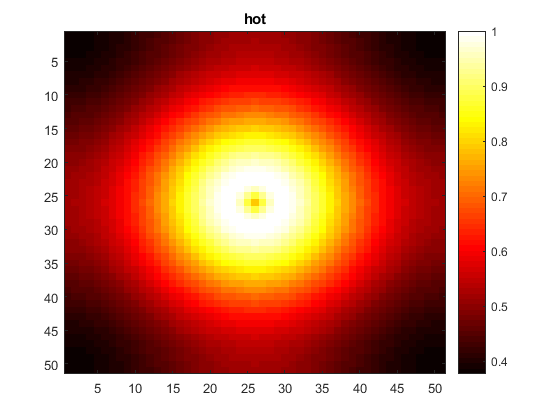

colormap('hot')
%image(mat,'CDataMapping','scaled')
%colorbar
title('hot')

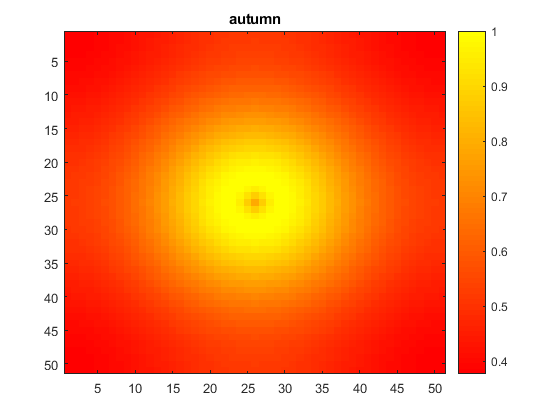

colormap('autumn')
%image(mat,'CDataMapping','scaled')
%colorbar
title('autumn')

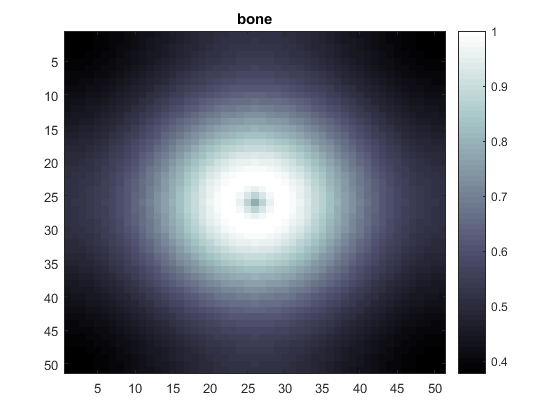

colormap('bone')
title('bone')

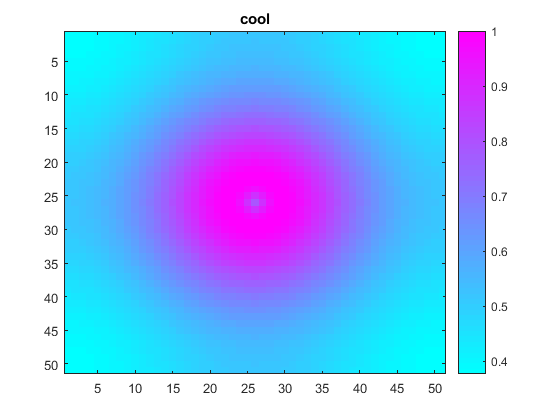

%image(mat,'CDataMapping','scaled')
%colorbar
colormap('cool')
title('cool')

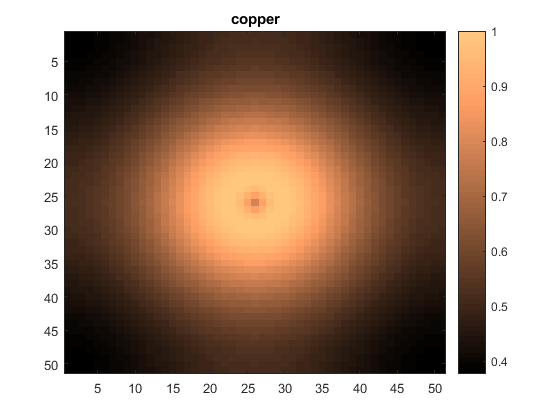

colormap('copper')
title('copper')

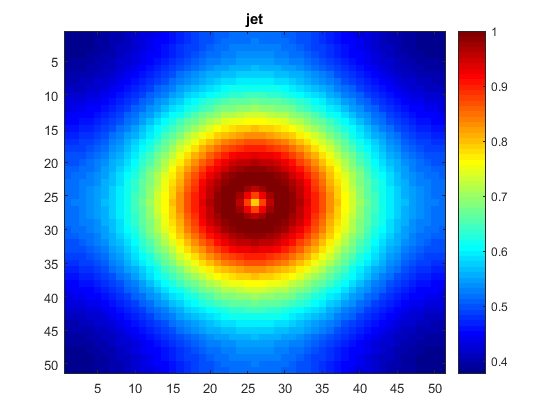

colormap('jet')
title('jet')

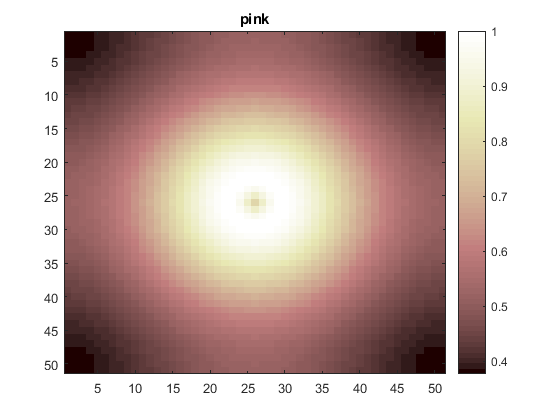

colormap('pink')
title('pink')

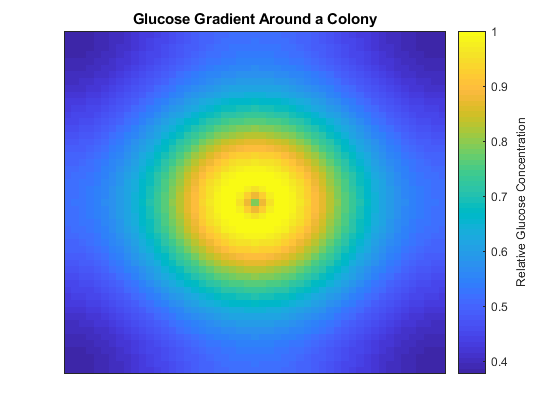

colormap('parula')
title('Glucose Gradient Around a Colony')
set(gca,'xtick',[])
set(gca,'ytick',[])
ylabel(c,'Relative Glucose Concentration')